# Pathplanning example

## Make points and make path

Points are in (x,y,z) coordinates. Also include first and second derivitive

This can be in any coordinate system, also with more than 3 dofs.

px = [0 0.5 1 0.5];
py = [0.5 1 0.5 0];
pz = [0 0 0 0];
p = [px;py;pz];


dpx = [0 1 0 -1];
dpy = [1 0 -1 0];
dpz = [0 0 0 0];
dp = [dpx;dpy;dpz];


ddpx = [1 0 -1 0];
ddpy = [0 -1 0 1];
ddpz = [0 0 0 0];
ddp = [ddpx;ddpy;ddpz];

%I call the pathplanning function and get return:
% h(s), dh = h'(s), ddh = h''(s)
[h,dh,ddh] = PathPlanning(p,dp,ddp);
n = size(p,1); %number of DOFS (index i)
N = size(p,2); %number of line segments (index j)


## Ploting path

Inserts numbers in path (h) to get 3rd order tensor "T_ijk" of points that can be plotted

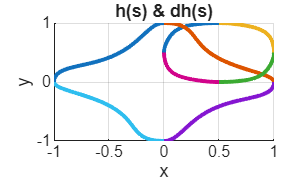

s = 0:0.01:1; %all line segments are parameterized from 0-1 (index j)


Position = zeros(n,N,length(s));
Velocity = zeros(n,N,length(s));

for i = 1:n %Dofs
    tau = 1;
    for j = 1:N %segments
        for k = 1:length(s) %place on segment
            h_ = h{i,j};
            dh_ = dh{i,j};
            Position(i,j,k) = h_(s(k));
            Velocity(i,j,k) = dh_(s(k));
            tau = tau+1;
        end
    end
    
end

figure('Name','path')
title('h(s) & dh(s)')
hold on
for j = 1:N
    pos = Position(:,j,:);
    vel = Velocity(:,j,:);
    plot3(pos(1,:),pos(2,:),pos(3,:),'LineWidth', 2)
    plot3(vel(1,:),vel(2,:),vel(3,:),'LineWidth', 2)
end
xlabel('x')
ylabel('y')
grid on
hold off

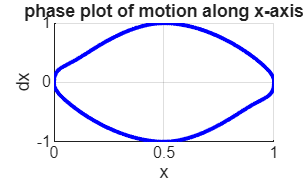


figure('Name','phase portrait x')
title('phase plot of motion along x-axis')
hold on
for j = 1:N
    pos = Position(:,j,:);
    vel = Velocity(:,j,:);
    plot(pos(1,:),vel(1,:),'color','b','LineWidth', 2);
end
xlabel('x')
ylabel('dx')
grid on
hold off

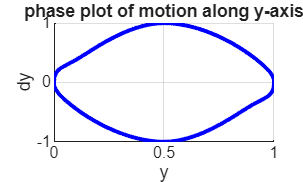


figure('Name','phase portrait y')
title('phase plot of motion along y-axis')
hold on
for j = 1:N
    pos = Position(:,j,:);
    vel = Velocity(:,j,:);
    plot(pos(2,:),vel(2,:),'color','b','LineWidth', 2);
end
xlabel('y')
ylabel('dy')
grid on
hold off